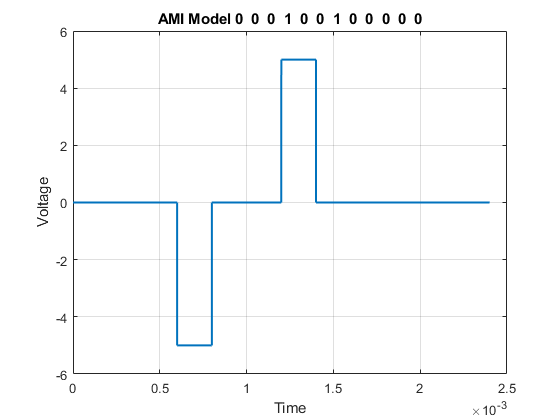

clc
close all
bit_stream = [0 0 0 1 0 0 1 0 0 0 0 0 ];
no_bits = length(bit_stream);
bit_rate = 5000;
pulse_rate= 1;
pulse_duration = 1/((pulse_rate)*(bit_rate));
no_pulse = no_bits*pulse_rate;
sample_per_pulse = 500;
fs = (sample_per_pulse)/(pulse_duration);
t = 0:1/fs:(no_pulse)*(pulse_duration);
no_sample= length(t);
dig_sig = zeros(1,no_sample);
max_volt = 5;
min_volt = -5;
neutral_volt = 0;
last_signal = max_volt;
inv_last_signal = min_volt;
for i = 1:no_bits
if bit_stream(i) == 1
dig_sig(((i-1)*(sample_per_pulse)+1):i*(sample_per_pulse))=inv_last_signal*ones(1,sample_per_pulse);
temp = last_signal;
last_signal = inv_last_signal;
inv_last_signal = temp;
else
dig_sig(((i-1)*(sample_per_pulse)+1):i*(sample_per_pulse)) = zeros*ones(1,sample_per_pulse);
end
end
plot(t,dig_sig,'linewidth',1.5)
grid on
xlabel('Time')
ylabel('Voltage')
ylim([(min_volt - (max_volt)*0.2)
(max_volt+max_volt*0.2)])
title(['AMI Model ',num2str(bit_stream),''])

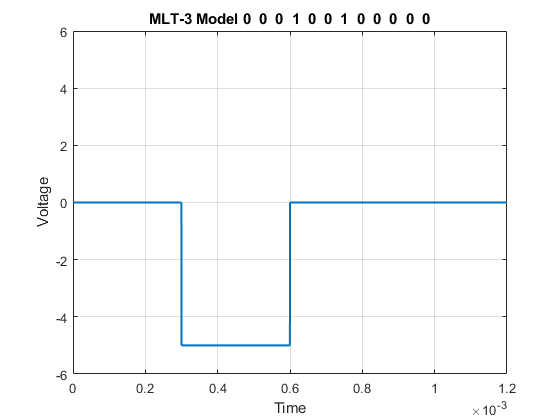

clc
close all
bit_stream = [0 0 0 1 0 0 1 0 0 0 0 0 ];
no_bits = length(bit_stream);
bit_rate = 10000;
pulse_per_bit = 1;
pulse_duration = 1/((pulse_per_bit)*(bit_rate));
no_pulses = no_bits*pulse_per_bit;
samples_per_pulse = 500;
fs = (samples_per_pulse)/(pulse_duration);
t = 0:1/fs:(no_pulses)*(pulse_duration);
no_samples = length(t);
dig_sig = zeros(1,no_samples);
max_voltage = 5;
min_voltage = -5;
neutral_voltage = 0;
last_state = neutral_voltage;
last_nonzero_state = max_voltage;
for i = 1:no_bits
if bit_stream(i) == 1
 if last_state == neutral_voltage
 if last_nonzero_state == max_voltage
dig_sig(((i-1)*(samples_per_pulse)+1):i*(samples_per_pulse))=min_voltage*ones(1,samples_per_pulse);
 last_nonzero_state = min_voltage;
 last_state = min_voltage;
 else
 dig_sig(((i-1)*(samples_per_pulse)+1):i*(samples_per_pulse))=max_voltage*ones(1,samples_per_puls);
 last_nonzero_state = max_voltage;
 last_state = max_voltage;
 end
 else
 dig_sig(((i-1)*(samples_per_pulse)+1):i*(samples_per_pulse)) = zeros*ones(1,samples_per_pulse);
 last_state = 0;
 end
else
 dig_sig(((i-1)*(samples_per_pulse)+1):i*(samples_per_pulse)) = last_state*ones(1,samples_per_pulse);
end
end
plot(t,dig_sig,'linewidth',1.5)
grid on
xlabel('Time')
ylabel('Voltage')
ylim([(min_voltage - (max_voltage)*0.2)
(max_voltage+max_voltage*0.2)])
title(['MLT-3 Model ',num2str(bit_stream),''])